wp=200*pi;ws=600*pi;Rp=3;Rs=12;
[n,wn]=buttord(wp,ws,Rp,Rs,'s')

n = 2

wn = 960.2345

[b,a]=butter(n,wn,'s')

b = 1.0e+05 *

         0         0    9.2205


a = 1.0e+05 *

    0.0000    0.0136    9.2205


[db,mag,pha,w]=freqs_m(b,a,500*2*pi)

db =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005   -0.0007   -0.0008   -0.0010   -0.0013   -0.0015   -0.0019   -0.0022   -0.0026   -0.0031   -0.0036   -0.0042   -0.0049   -0.0056   -0.0064   -0.0073   -0.0083   -0.0094   -0.0106   -0.0119   -0.0134   -0.0149   -0.0166   -0.0184   -0.0203   -0.0224   -0.0247   -0.0271   -0.0297   -0.0325   -0.0355   -0.0387   -0.0421   -0.0457


mag =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9997    0.9996    0.9996    0.9995    0.9994    0.9994    0.9993    0.9992    0.9990    0.9989    0.9988    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9963    0.9959    0.9956    0.9952    0.9948


pha =          0   -0.0093   -0.0185   -0.0278   -0.0370   -0.0463   -0.0556   -0.0648   -0.0741   -0.0834   -0.0927   -0.1020   -0.1113   -0.1206   -0.1299   -0.1392   -0.1486   -0.1580   -0.1673   -0.1767   -0.1861   -0.1955   -0.2050   -0.2144   -0.2239   -0.2334   -0.2429   -0.2524   -0.2619   -0.2715   -0.2811   -0.2907   -0.3003   -0.3100   -0.3197   -0.3294   -0.3391   -0.3488   -0.3586   -0.3684   -0.3782   -0.3881   -0.3980   -0.4079   -0.4178   -0.4278   -0.4378   -0.4478   -0.4579   -0.4679


w = 1.0e+03 *

         0    0.0063    0.0126    0.0188    0.0251    0.0314    0.0377    0.0440    0.0503    0.0565    0.0628    0.0691    0.0754    0.0817    0.0880    0.0942    0.1005    0.1068    0.1131    0.1194    0.1257    0.1319    0.1382    0.1445    0.1508    0.1571    0.1634    0.1696    0.1759    0.1822    0.1885    0.1948    0.2011    0.2073    0.2136    0.2199    0.2262    0.2325    0.2388    0.2450    0.2513    0.2576    0.2639    0.2702    0.2765    0.2827    0.2890    0.2953    0.3016    0.3079


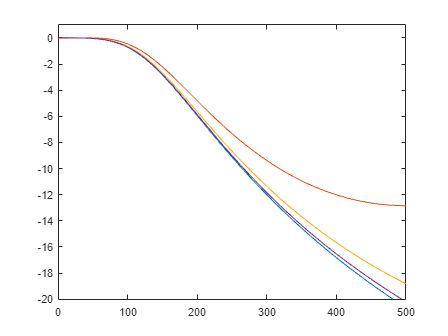

plot(w/(2*pi),db);axis([0,500,-20,1]);
hold on
%set frequency to 1Khz
fs=1000;[bz,az]=impinvar(b,a,fs);
[db,mag,pha,grd,w]=freqz_m(bz,az);
plot(0.5*fs*w/pi,db);axis([0,500,-20,1]);
%reset frequency to 2Khz
fs=2000;[bz,az]=impinvar(b,a,fs);
[db,mag,pha,grd,w]=freqz_m(bz,az);
plot(0.5*fs*w/pi,db);axis([0,500,-20,1])
%reset frequency to 4Khz
fs=4000;[bz,az]=impinvar(b,a,fs);
[db,mag,pha,grd,w]=freqz_m(bz,az);
plot(0.5*fs*w/pi,db);axis([0,500,-20,1])
hold off